## 211018_3magnetites_2A_0Hz

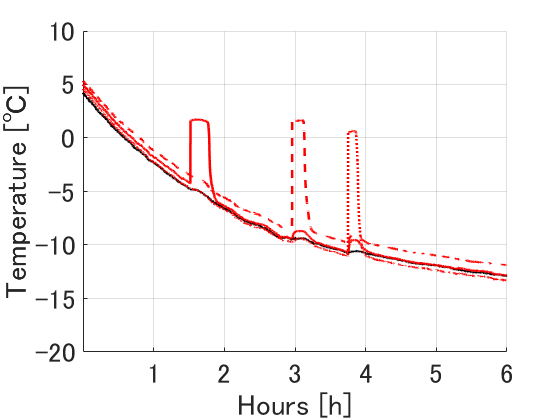

clearvars

time_setting=[5,6];%計測間隔(sec) 測定最終時間(hour)
load("result_all.mat");
fig1=figure();
name="211018_3magnetites_2A_0Hz";
result_temp=plotdata(a211018_3magnetites_2A_0Hz,time_setting,fig1,name);

a211018_3magnetites_2A_0Hz_10e2=result_temp(:,1);
a211018_3magnetites_2A_0Hz_10e3=result_temp(:,2);
a211018_3magnetites_2A_0Hz_10e4=result_temp(:,3);
result_new=table(a211018_3magnetites_2A_0Hz_10e2,a211018_3magnetites_2A_0Hz_10e3,a211018_3magnetites_2A_0Hz_10e4);
ind = contains(result.Properties.VariableNames,result_new.Properties.VariableNames);

j=1;
for i=1:length(ind)
    if ind(i)==1
        result(:,i)=result_new(:,j);
        j=j+1;
    end
end

if j==1
    result=[result,result_new];
end


clearvars a211018_3magnetites_2A_0Hz_10e2 a211018_3magnetites_2A_0Hz_10e3 a211018_3magnetites_2A_0Hz_10e4...
    hour i j name ind result_temp result_new
save('result_all');

## 211020_3magnetites_2A_10Hz

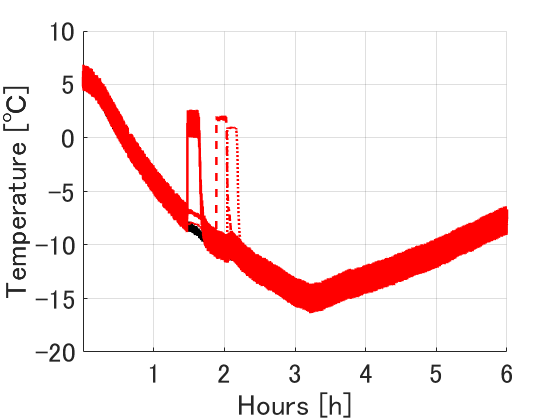

clearvars

time_setting=[5,6];%計測間隔(sec) 測定最終時間(hour)
load("result_all.mat");
fig1=figure();
name="211020_3magnetites_2A_10Hz";
result_temp=plotdata(a211020_3magnetites_2A_10Hz(300:12283,:),time_setting,fig1,name);

a211020_3magnetites_2A_10Hz_10e2=result_temp(:,1);
a211020_3magnetites_2A_10Hz_10e3=result_temp(:,2);
a211020_3magnetites_2A_10Hz_10e4=result_temp(:,3);
result_new=table(a211020_3magnetites_2A_10Hz_10e2,a211020_3magnetites_2A_10Hz_10e3,a211020_3magnetites_2A_10Hz_10e4);
ind = contains(result.Properties.VariableNames,result_new.Properties.VariableNames);

j=1;
for i=1:length(ind)
    if ind(i)==1
        result(:,i)=result_new(:,j);
        j=j+1;
    end
end

if j==1
    result=[result,result_new];
end


clearvars a211020_3magnetites_2A_10Hz_10e2 a211020_3magnetites_2A_10Hz_10e3 a211020_3magnetites_2A_10Hz_10e4...
    hour i j name ind result_temp result_new
save('result_all');

## 210928_3water_0A_0Hz

clearvars

time_setting=[5,6];%計測間隔(sec) 測定最終時間(hour)
load("result_all.mat");
fig1=figure();
name="210928_3water_0A_0Hz";
result_temp=plotdata(a210928_3water_0A_0Hz,time_setting,fig1,name);
a211020_3magnetites_2A_0Hz_10e2=result_temp(:,1);
a211020_3magnetites_2A_10Hz_10e3=result_temp(:,2);
a211020_3magnetites_2A_10Hz_10e4=result_temp(:,3);
result_new=table(a211020_3magnetites_2A_0Hz_10e2,a211020_3magnetites_2A_10Hz_10e3,a211020_3magnetites_2A_10Hz_10e4);
ind = contains(result.Properties.VariableNames,result_new.Properties.VariableNames);

j=1;
for i=1:length(ind)
    if ind(i)==1
        result(:,i)=result_new(:,j);
        j=j+1;
    end
end

if j==1
    result=[result,result_new];
end


clearvars a210928_3water_0A_0Hz_1 a210928_3water_0A_0Hz_2 a210928_3water_0A_0Hz_3...
    hour i j name ind result_temp result_new
save('result_all');

## 210929_3water_4V_10Hz

clearvars

time_setting=[5,6];%計測間隔(sec) 測定最終時間(hour)
load("result_all.mat");
fig2=figure();
name="210929_3water_4V_10Hz";
result_temp=plotdata(a210929_3water_4V_10Hz,time_setting,fig2,name);
a210929_3water_4V_10Hz_1=result_temp(:,1);
a210929_3water_4V_10Hz_2=result_temp(:,2);
a210929_3water_4V_10Hz_3=result_temp(:,3);
result_new=table(a210929_3water_4V_10Hz_1,a210929_3water_4V_10Hz_2,a210929_3water_4V_10Hz_3);
ind = contains(result.Properties.VariableNames,result_new.Properties.VariableNames);

j=1;
for i=1:length(ind)
    if ind(i)==1
        result(:,i)=result_new(:,j);
        j=j+1;
    end
end

if j==1
    result=[result,result_new];
end
clearvars a210929_3water_4V_10Hz_1 a210929_3water_4V_10Hz_2 a210929_3water_4V_10Hz_3...
    hour i j name ind result_temp result_new
save('result_all');

## summary

clearvars

load("result_all.mat");
mag_ms=[result.a210928_3water_0A_0Hz_1,result.a210928_3water_0A_0Hz_2,result.a210928_3water_0A_0Hz_3];
mag_ps=[result.a210929_3water_4V_10Hz_1,result.a210929_3water_4V_10Hz_2,result.a210929_3water_4V_10Hz_3];

mag_ms_mean=mean(mag_ms,2);
mag_ms_se=std(mag_ms,0,2)/sqrt(length(mag_ms));

mag_ps_mean=mean(mag_ps,2);
mag_ps_se=std(mag_ps,0,2)/sqrt(length(mag_ps));

fig3=figure();
hold on
bar([mag_ms_mean(1) mag_ps_mean(1)])
errorbar([mag_ms_mean(1) mag_ps_mean(1)],[mag_ms_se(1) mag_ps_se(1)],"vertical",'k',"LineStyle","none")
set(gca,"fontSize",20)
xticks([1 2])
xticklabels({'0V 0Hz','4V 10Hz'})
ylabel('Temperature [℃]');
hold off
saveas(fig3,'figure/overtemprature.png')

fig4=figure();
hold on
bar([mag_ms_mean(2) mag_ps_mean(2)])
errorbar([mag_ms_mean(2) mag_ps_mean(2)],[mag_ms_se(2) mag_ps_se(2)],"vertical",'k',"LineStyle","none")
set(gca,"fontSize",20)
xticks([1 2])
xticklabels({'0V 0Hz','4V 10Hz'})
ylabel('Time to freeze [s]');
hold off
saveas(fig4,'figure/coolingtime.png')

output1=table2array(a210928_3water_0A_0Hz(:,3:6));
output2=table2array(a210929_3water_4V_10Hz(:,3:6));
start=find(output1(:,1)<5, 1 );
time=(0:time_setting(1):size(output1)*time_setting(1)-1).'/3600;
time=time-time(start);
s=3600;

fig5=figure();
hold on
plot(time(1000:1100),output1(1000:1100,1))
plot(time(1000:1100),output2(1000:1100,1))
set(gca,"fontSize",20)
legend('0V 0Hz','4V 10Hz')
xlabel('Hours [h]');
ylabel('Temperature [℃]');
saveas(fig5,'figure/compaire2_large.png')

function r=plotdata(a,h,~,name)
    output=table2array(a(:,3:6));
    start=find(output(:,2)<5, 1 );
    finish=3600*h(2)/h(1)+start;
    time=(0:h(1):size(a)*h(1)-1).'/3600;
    time=time-time(start);
    f=figure;
    hold on
    plot(time(start:finish),output(start:finish,1),'k-',"LineWidth",2)
    plot(time(start:finish),output(start:finish,2),'r-',"LineWidth",2)
    plot(time(start:finish),output(start:finish,3),'r--',"LineWidth",2)
    plot(time(start:finish),output(start:finish,4),'r:',"LineWidth",2)
    xlabel('Hours [h]');
    ylabel('Temperature [℃]');
    xticks([1,2,3,4,5,6]);
    xticklabels({'1','2','3','4','5','6'});
    grid on
    ylim([-20 10]);
    hold off;
    set(gca,"fontSize",20)
    saveas(f,"figure/"+name+".png");
    for i=2:4
        [r(1,i-1),r(2,i-1)]=find_peak(output(start:finish,i),h);
    end
end 

function [temp,gaptime]=find_peak(a,h)
    %a=movmean(a,20);
    div=a(2:length(a))-a(1:length(a)-1);
    meanx=mean(a(div==max(div)):div(div==max(div)));
    temp=a(div==max(div));
    gaptimestart=find(a==temp);
    gaptime=nnz(a(gaptimestart+1:end)>meanx/2)*h(1);
end

function save_all()
    clearvars name
    save('result_all');
end